clear; clc;
datapath = pwd;

## Import the data

Loads the data and modifies the data where Stage 3 and 4 are combined. 

% Initialize cell arrays to store loaded data
dataN = cell(1, 11);
dataP = cell(1, 11);

% Load data from files N1 to N11
for j = 1:11    
    filenameN = fullfile(datapath, ['combinedN' num2str(j) '.mat']);
    loadeddataN = load(filenameN);
    combinedN = loadeddataN.(['combinedN' num2str(j)]); 
    
    % Extract sleep stages and PSD data for each subject
    subject_dataN = struct();
    for k = 1:numel(combinedN)
        sleep_stage = combinedN(k).sleep_stage;
        psd_data = combinedN(k).psd_data;
        subject_dataN(k).sleep_stage = sleep_stage;
        subject_dataN(k).psd_data = psd_data;
    end

    % Modify sleep stages
    idx_stage4N = strcmp({subject_dataN.sleep_stage}, 'Stage 4');
    [subject_dataN(idx_stage4N).sleep_stage] = deal('Stage 3');
    idx_movementN = strcmp({subject_dataN.sleep_stage}, 'Movement');
    subject_dataN = subject_dataN(~idx_movementN);

    dataN{j} = subject_dataN;
end

% Load data from files P1 to P11
for j = 1:11
    filenameP = fullfile(datapath, ['combinedP' num2str(j) '.mat']);
    loadeddataP = load(filenameP);
    combinedP = loadeddataP.(['combinedP' num2str(j)]); 
    
    % Extract sleep stages and PSD data for each subject
    subject_dataP = struct();
    for k = 1:numel(combinedP)
        sleep_stage = combinedP(k).sleep_stage;
        psd_data = combinedP(k).psd_data;
        subject_dataP(k).sleep_stage = sleep_stage;
        subject_dataP(k).psd_data = psd_data;
    end
    
     % Modify sleep stages
    idx_stage4P = strcmp({subject_dataP.sleep_stage}, 'Stage 4');
    [subject_dataP(idx_stage4P).sleep_stage] = deal('Stage 3');
    idx_movementP = strcmp({subject_dataP.sleep_stage}, 'Movement');
    subject_dataP = subject_dataP(~idx_movementP);

    dataP{j} = subject_dataP;
end

% Ensure consistency of data dimensions
assert(isequal(size(dataN), size(dataP)), 'Dimensions of data_N and data_P are not consistent.');     

## Feature Extraction

Extraction of sleep stages and PSD data and storing into their respective cell arrays.

% Combine all sleep stages from data_N and data_P
all_data = [dataN, dataP];

% Initialize cell arrays to store sleep stages and PSD data
all_sleep_stages = cell(1, numel(all_data));
all_psd_data = cell(1, numel(all_data));

% Iterate over each subject's data
for subject_idx = 1:numel(all_data)
    % Extract sleep stages and PSD data for the current subject
    subject_data = all_data{subject_idx};
    
    % Extract sleep stages
    sleep_stages = {subject_data.sleep_stage};
    all_sleep_stages{subject_idx} = sleep_stages;
    
    % Extract PSD data
    psd_data = {subject_data.psd_data};
    all_psd_data{subject_idx} = psd_data; %1x22 cell
end

all_psd_data

all_psd_data = 1×22 cell array
    {1×920 cell}    {1×922 cell}    {1×1043 cell}    {1×874 cell}    {1×957 cell}    {1×949 cell}    {1×959 cell}    {1×937 cell}    {1×968 cell}    {1×953 cell}    {1×946 cell}    {1×954 cell}    {1×873 cell}    {1×959 cell}    {1×954 cell}    {1×905 cell}    {1×918 cell}    {1×958 cell}    {1×952 cell}    {1×662 cell}    {1×939 cell}    {1×1043 cell}


all_sleep_stages

all_sleep_stages = 1×22 cell array
    {1×920 cell}    {1×922 cell}    {1×1043 cell}    {1×874 cell}    {1×957 cell}    {1×949 cell}    {1×959 cell}    {1×937 cell}    {1×968 cell}    {1×953 cell}    {1×946 cell}    {1×954 cell}    {1×873 cell}    {1×959 cell}    {1×954 cell}    {1×905 cell}    {1×918 cell}    {1×958 cell}    {1×952 cell}    {1×662 cell}    {1×939 cell}    {1×1043 cell}


## Spectral power analysis

Average of spectral values for each frequency band from each subject. 

% Define frequency bands and sleep stages
frequency_bands = {'slowwave', 'theta', 'alpha', 'spindle'};
num_subjects = numel(all_psd_data);

% Initialize cell arrays to store PSD values for each subject and each frequency band
psd_values_by_subject = cell(num_subjects, numel(frequency_bands));

% Iterate over each frequency band
for band_idx = 1:numel(frequency_bands)
    % Iterate over each subject's PSD data
    for subject_idx = 1:num_subjects
        % Extract PSD data for the current subject
        psd_data_subject = all_psd_data{subject_idx};

        % Initialize array to store PSD values for the current subject and band
        subject_band_psd = [];

        % Iterate over each cell (data point) for this subject
        for cell_idx = 1:numel(psd_data_subject)
            % Extract the PSD value for the current frequency band
            psd_value = psd_data_subject{cell_idx}.(frequency_bands{band_idx});

            % Add PSD value to the array for the current subject and band
            subject_band_psd = [subject_band_psd, psd_value];
        end

        % Store PSD values for the current subject and band
        psd_values_by_subject{subject_idx, band_idx} = subject_band_psd;
    end
end

% Define user-friendly names for frequency bands
frequency_bands_display = {'Delta', 'Theta', 'Alpha', 'Sigma'};

for subject_idx = 1:num_subjects
    % Create a new figure for each subject
    figure;

    % Define a common title for all frequency bands
    sgtitle(sprintf('Subject %d', subject_idx));

    for band_idx = 1:numel(frequency_bands)
        % Extract PSD values for the current frequency band and subject
        band_data = psd_values_by_subject{subject_idx, band_idx};
        % Extract sleep stages for the current subject
        subject_sleep_stages = all_sleep_stages{subject_idx};

        sleep_stage_labels = cellstr(subject_sleep_stages);

        % Create a subplot for each band within the figure
        subplot(1, numel(frequency_bands), band_idx);

        % Plot boxplot for the current frequency band and subject
        boxplot(band_data, sleep_stage_labels);
        title(sprintf('%s Band', frequency_bands_display{band_idx})); % Use user-friendly names for plot titles
        ylabel('PSD Value');
        xtickangle(45); % Rotate x-axis labels for better readability
        %xticklabels(sleep_stage_order);
    end
end


% Define frequency bands of interest and their corresponding frequency ranges
frequency_bands = {'slowwave', 'theta', 'alpha', 'spindle'};

% Initialize cell array to store average spectral power for each subject and each frequency band
num_bands          = numel(frequency_bands);
avg_spectral_power = cell(num_subjects, num_bands);

% Iterate over each subject's PSD data and corresponding concatenated data
for subject_idx = 1:num_subjects
    % Extract PSD data for the current subject
    psd_data_subject = all_psd_data{subject_idx};

    % Initialize array to store average PSD values for this subject
    avg_psd_subject = zeros(1, num_bands);

    % Initialize array to store total PSD values for each frequency band
    total_psd_band = zeros(1, num_bands);

    % Iterate over each cell (data point) for this subject
    for cell_idx = 1:numel(psd_data_subject)
        % Iterate over each frequency band
        for band_idx = 1:num_bands
            % Extract frequency range for the current band
            band_name = frequency_bands{band_idx};

            % Access the structure within the cell array and then extract the PSD values for the current frequency band
            psd_values_band = psd_data_subject{cell_idx}.(band_name);

            % Accumulate the PSD values for this frequency band
            total_psd_band(band_idx) = total_psd_band(band_idx) + sum(psd_values_band);
        end
    end
    avg_psd_subject = total_psd_band / numel(psd_data_subject);        % Calculate the average PSD values for each frequency band
    avg_spectral_power(subject_idx, :) = num2cell(avg_psd_subject);    % Store the average PSD values for this subject
end

% Calculate standard deviation for each frequency band across all subjects
std_per_band = std(cell2mat(avg_spectral_power), 0, 1)

% Assign band labels to the columns (frequency bands)
band_labels = frequency_bands;

% Assign subject labels to the rows if available
% Replace the following line with your subject labels if available
subject_labels = cellstr(num2str((1:num_subjects)', 'Subject %d'));

% Create a table to display the average spectral power with row and column labels
avg_spectral_power_table = array2table(avg_spectral_power, 'RowNames', subject_labels, 'VariableNames', band_labels)

% Convert cell to matrix
psd_values = cell2mat(avg_spectral_power);
psd_valuesN = psd_values(1:11, :);
std_N = std(psd_valuesN, 0, 1)

psd_valuesP = psd_values(12:end, :);
std_P = std(psd_valuesP, 0, 1)

figure;
% Create a box plot
boxplot(psd_values, 'Labels', frequency_bands_display);
xlabel('Frequency Bands');
ylabel('Average Spectral Power');

title('Average Spectral Power Across Frequency Bands');

% Create figure with specified size
figure('Units', 'inches', 'Position', [0, 0, 10, 6]);

% Create subplot
subplot(2, 1, 1);
boxplot(psd_valuesN, 'Labels', frequency_bands_display);
xlabel('Frequency Bands');
ylabel('Average Spectral Power');
title('Normal Subjects');

% Create subplot
subplot(2, 1, 2);
boxplot(psd_valuesP, 'Labels', frequency_bands_display);
xlabel('Frequency Bands');
ylabel('Average Spectral Power');
title('Psychophysiological Insomnia Subjects');

% Initialize arrays to store RQA measures for each subject
num_recurrences = zeros(num_subjects, 1);
recurrence_rate = zeros(num_subjects, 1);
determinism = zeros(num_subjects, 1);
average_diag_line = zeros(num_subjects, 1);

% Threshold for recurrence plot
threshold = 0.3;

% Iterate over each subject's PSD data
for subject_idx = 1:numel(all_psd_data)
    % Extract PSD data for the current subject
    psd_data_subject_cells = all_psd_data{subject_idx}; % Access the PSD data for the current subject

    % Initialize cell array to store PSD vectors for each frequency band
    psd_vectors = cell(num_bands, 1);

    % Iterate over each frequency band
    for band_idx = 1:num_bands
        % Extract frequency band label
        band_label = frequency_bands{band_idx};

        % Extract PSD values for the current frequency band
        psd_values_band = psd_data_subject_cells{band_idx};

        % If the PSD data is stored as a structure, extract the numerical data
        for i = 1:length(psd_data_subject_cells)
            % Access the ith element of the cell array
            psd_values_band_i = psd_data_subject_cells{i}; 
            psd_values_band_i = psd_values_band_i.(band_label);

            % Store the PSD vector for this frequency band
            psd_vectors{band_idx} = [psd_vectors{band_idx}; psd_values_band_i];
        end
    end

    % Concatenate PSD vectors for all frequency bands
    concatenated_psd = cat(2, psd_vectors{:});

    % Compute pairwise similarity matrix
    similarity_matrix = pdist2(concatenated_psd', concatenated_psd');

    % Threshold the similarity matrix to obtain the recurrence plot
    recurrence_matrix = similarity_matrix >= threshold; 

    % Display recurrence plot for this subject
    figure;
    imagesc(recurrence_matrix);
    colormap(gray);
    title(['Recurrence Plot - Subject ', num2str(subject_idx)]);
    xlabel('Time (s)');
    ylabel('Time (s)');
    %colorbar;

    % Save the figure as an image file
    filename = ['Recurrence_Plot_Subject_', num2str(subject_idx), '.png'];
    saveas(gcf, filename);
    pause(0.1)

    % Compute RQA measures
    num_recurrences(subject_idx) = sum(recurrence_matrix, 'all');
    num_total_recurrences = num_recurrences(subject_idx) - sum(diag(recurrence_matrix));    % Compute the total number of recurrence points excluding the main diagonal
    recurrence_rate(subject_idx) = num_total_recurrences / (numel(recurrence_matrix) - numel(diag(recurrence_matrix)));    % Compute recurrence rate
    sum_diag = sum(sum(recurrence_matrix - eye(size(recurrence_matrix))));    % Compute the sum of diagonal elements excluding the main diagonal
    sum_all = sum(recurrence_matrix, 'all');    % Compute the sum of all elements in the recurrence matrix

   % Calculate determinism
    if sum_all ~= 0
        determinism(subject_idx) = sum_diag / sum_all;
    else
        determinism(subject_idx) = 0;
    end

    average_diag_line(subject_idx) = sum_diag / sum(sum(recurrence_matrix ~= 0));    % Calculate average diagonal line
    close(gcf);
end

% Display RQA measures
disp('Recurrence Quantification Analysis (RQA) Measures:');
disp('--------------------------------------------------');
disp(['Number of Recurrences: ', num2str(num_recurrences')]);
disp(['Recurrence Rate: ', num2str(recurrence_rate')]);
disp(['Determinism: ', num2str(determinism')]);
disp(['Average Diagonal Line Length: ', num2str(average_diag_line')]);

dN = mean(determinism(1:11, :))
dP = mean(determinism(12:end))
detall = mean(determinism)

Compute for the average of each frequency band across all subjects and the relative power of each band. 

% Initialize array to store the sum of PSD values for each band
sum_psd_values_band = zeros(1, num_bands);

% Sum up the PSD values for each band across all subjects
for band_idx = 1:num_bands
    % Extract the PSD values for the current band across all subjects
    psd_values_band = [avg_spectral_power{:, band_idx}];

    % Calculate the sum of PSD values for the current band
    sum_psd_values_band(band_idx) = sum(psd_values_band);   
end

overall_avg_psd_values = sum_psd_values_band / num_subjects         % Calculate the overall average PSD values for each band
total_power            = sum(sum_psd_values_band)                   % Calculate the total power across all frequency bands
relative_power_values  = sum_psd_values_band / total_power          % Calculate the relative power values for each band

avg_spectral_powerN = avg_spectral_power(1:11, :);

% Initialize array to store the sum of PSD values for each band
sum_psd_values_N = zeros(1, num_bands);

% Sum up the PSD values for each band across all subjects
for band_idx = 1:num_bands
    % Extract the PSD values for the current band across all subjects
    psd_values_band = [avg_spectral_powerN{:, band_idx}];

    % Calculate the sum of PSD values for the current band
    sum_psd_values_N(band_idx) = sum(psd_values_band);   
end

N_avg_psd_values       = sum_psd_values_N / numel(avg_spectral_powerN)     % Calculate the overall average PSD values for each band
total_power            = sum(sum_psd_values_N)                                  % Calculate the total power across all frequency bands
relative_power_valuesN = sum_psd_values_N / total_power               % Calculate the relative power values for each band

avg_spectral_powerP = avg_spectral_power(12:end, :);

% Initialize array to store the sum of PSD values for each band
sum_psd_values_P = zeros(1, num_bands);

% Sum up the PSD values for each band across all subjects
for band_idx = 1:num_bands
    % Extract the PSD values for the current band across all subjects
    psd_values_band = [avg_spectral_powerP{:, band_idx}];

    % Calculate the sum of PSD values for the current band
    sum_psd_values_P(band_idx) = sum(psd_values_band);   
end

P_avg_psd_values = sum_psd_values_P / numel(avg_spectral_powerP)      % Calculate the overall average PSD values for each band
total_power = sum(sum_psd_values_P)                                   % Calculate the total power across all frequency bands
relative_power_valuesP = sum_psd_values_P / total_power               % Calculate the relative power values for each band

## Sleep Architecture 

Plot separate histograms for normal and psychophsysiological insomnia sleep subjects.

% Initialize arrays to store sleep stages for subjects "N" and "P"
sleep_stages_N = [];
sleep_stages_P = [];

% Extract sleep stages for subjects "N" and "P"
for subject_idx = 1:numel(data_N)
    sleep_stages_N = [sleep_stages_N, all_sleep_stages{subject_idx}];
end

for subject_idx = 1:numel(data_P)
    sleep_stages_P = [sleep_stages_P, all_sleep_stages{subject_idx + numel(data_N)}];
end

figure;
subplot(2,1,1);
histogram(categorical(sleep_stages_N));
title('Histogram of Sleep Stages for Normal Subjects');
xlabel('Sleep Stage');
ylabel('Frequency');

subplot(2,1,2);
histogram(categorical(sleep_stages_P));
title('Histogram of Sleep Stages for Psychophysiological Insomnia Subjects');
xlabel('Sleep Stage');
ylabel('Frequency');

XTrain          = (cat(2, all_psd_data{:}))';
num_train_cells = numel(XTrain);
XTrainData      = cell(num_train_cells, 1);

% Loop over each cell in XTrain
for i = 1:num_train_cells
    % Extract the struct array from the current cell
    sequence_structs = XTrain{i};

    % Initialize a cell array to store data from each struct
    num_structs = numel(sequence_structs);
    sequence_data = cell(1, num_structs);

        % Extract data from each struct
        for j = 1:num_structs
            % Access the fields of the struct
            fields = fieldnames(sequence_structs(j));
            struct_data = cell(numel(fields), 1);
                for k = 1:numel(fields)
                    % Extract data from the field, skipping padded zeros
                    struct_data{k} = sequence_structs(j).(fields{k})(sequence_structs(j).(fields{k}) ~= 0);
                end
            % Concatenate the data from all fields into a single row vector
            max_length = max(cellfun(@numel, struct_data));
            padded_data = cellfun(@(x) [x(:); zeros(max_length - numel(x), 1)], struct_data, 'UniformOutput', false);
            sequence_data{j} = vertcat(padded_data{:});
        end
        % Concatenate the data from all structs into a single matrix
        XTrainData{i} = vertcat(sequence_data{:});
end

maxSequenceLengthTrain = max(cellfun(@numel, XTrainData));
XTrainMatrix = zeros(numel(XTrainData), maxSequenceLengthTrain); 

% Convert cell array of sequences to a matrix
for i = 1:numel(XTrainData)
    sequence = XTrainData{i};
    sequenceLength = numel(sequence);   
    XTrainMatrix(i, 1:sequenceLength) = sequence;
end

## Convert sleep stages to categorical array

Transforming the nested cell into a double before categorical conversion.

% Define the label mapping
label_mapping = containers.Map({'Wake', 'Rem', 'Stage 1', 'Stage 2', 'Stage 3'}, {1, 4, 2, 3, 5});

TrainLabelsNum = cell(size(all_sleep_stages));
for i = 1:numel(all_sleep_stages)
    num_elements = numel(all_sleep_stages{i});
    TrainLabelsNum{i} = zeros(1, num_elements);  
    for j = 1:num_elements
        label_idx = label_mapping(all_sleep_stages{i}{j});
        TrainLabelsNum{i}(j) = label_idx;
    end
end

YTrainLabels = categorical(cat(2, TrainLabelsNum{:}), 1:5)';

## Calculate the class weights for imbalanced classes

The weights and their respective labels (normalized) are displayed.     

numClasses = 5;
counts     = zeros(1, numClasses); % Initialize counts for each class label

% Compute the counts of each class label
for i = 1:numel(all_sleep_stages)
    % Extract sleep stages for the current subject
    sleep_stages = all_sleep_stages{i};

    % Iterate over sleep stages
    for j = 1:numel(sleep_stages)
        label = label_mapping(sleep_stages{j}); % Convert sleep stage to label
        if label >= 1 && label <= numClasses
            counts(label) = counts(label) + 1;
        end
    end
end

% Calculate the class weights
classWeights = 1./counts;
classWeights = classWeights ./ sum(classWeights); % Normalize the class weights

% Store class weights along with their corresponding labels
classWeightsWithLabels = cell(1, numClasses);
for label = 1:numClasses
    classWeightsWithLabels{label} = struct('Label', label, 'Weight', classWeights(label));
end

% Display class weights along with their corresponding sleep stages
keys = label_mapping.keys;
for i = 1:numel(keys)
    sleep_stage = keys{i};
    label = label_mapping(sleep_stage);
    fprintf('Sleep Stage: %s, Weight: %f\n', sleep_stage, classWeights(label));
end

Sleep Stage: Rem, Weight: 0.374058
Sleep Stage: Stage 1, Weight: 0.104061
Sleep Stage: Stage 2, Weight: 0.190688
Sleep Stage: Stage 3, Weight: 0.179370
Sleep Stage: Wake, Weight: 0.151823


%Apply weights to the training data
weightedXTrainMatrix = zeros(size(XTrainMatrix));  % Initialize matrix for weighted data
for i = 1:numel(YTrainLabels)
    weightedXTrainMatrix(i, :) = XTrainMatrix(i, :) * classWeights(YTrainLabels(i));
end
weightedXTrainMatrix

weightedXTrainMatrix =     0.0408    0.0176    0.0231    0.0322
    0.0368    0.0157    0.0208    0.0290
    0.0395    0.0169    0.0211    0.0306
    0.0436    0.0187    0.0245    0.0346
    0.0539    0.0234    0.0274    0.0389
    0.0591    0.0259    0.0304    0.0435
    0.0552    0.0242    0.0289    0.0405
    0.0537    0.0234    0.0284    0.0391
    0.0561    0.0239    0.0299    0.0412
    0.0514    0.0221    0.0260    0.0384


YTrainLabels

YTrainLabels = 20545×1 categorical array
     3 
     5 
     5 
     5 
     5 
     5 
     5 
     5 
     5 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     2 
     5 
     3 
     3 
     2 
     2 
     3 
     2 
     4 
     4 
     4 
     4 


## Train model

% Call the trainClassifier function and pass your data and labels
[trainedClassifier, validationAccuracy] = trainData(weightedXTrainMatrix, YTrainLabels);

% Now you have the trained classifier and validation accuracy
disp('Validation Accuracy:');

Validation Accuracy:


disp(validationAccuracy);

    0.7639




% Perform cross-validation
partitionedModel = crossval(trainedClassifier.ClassificationNeuralNetwork, 'KFold', 5);         

% Compute validation predictions
[validationPredictions, validationScores] = kfoldPredict(partitionedModel);

% Convert the categorical labels to numeric
LabelsNumeric = grp2idx(YTrainLabels); 
trueLabelsCategorical = categorical(LabelsNumeric);

% Convert categorical predictions to numeric
validationPredictionsNumeric = double(validationPredictions);

% Compute total accuracy
totalAccuracy = sum(LabelsNumeric == validationPredictionsNumeric) / numel(LabelsNumeric);

disp('Total Accuracy:');

Total Accuracy:


disp(totalAccuracy*100);

   76.2083



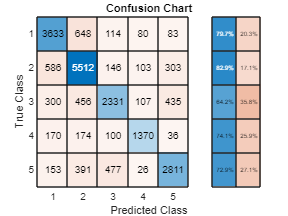


figure; 
confChart = confusionchart(trueLabelsCategorical, validationPredictions, 'RowSummary', 'row-normalized'); 
confChart.Title = 'Confusion Chart';

DataTest = array2table(weightedXTrainMatrix);
YTestLabelsTable = array2table(YTrainLabels);
testData = [DataTest, YTestLabelsTable]

testData = 20545×5 table
    weightedXTrainMatrix1    weightedXTrainMatrix2    weightedXTrainMatrix3    weightedXTrainMatrix4    YTrainLabels
    _____________________    _____________________    _____________________    _____________________    ____________

          0.040778                 0.017586                 0.023058                 0.032156                3      
          0.036834                  0.01568                 0.020846                 0.029002                5      
          0.039473                 0.016931                 0.021139                 0.030575                5      
          0.043606                 0.018708                 0.024528                 0.034596                5      
          0.053892                 0.023379                 0.027429                 0.038867         

% Extract the confusion matrix data
confMatrix = confChart.NormalizedValues;

% Initialize an empty cell array to store misclassified stages information
misclassifiedStages = {};

% Loop through the confusion matrix to find misclassifications
for i = 1:size(confMatrix, 1)
    for j = 1:size(confMatrix, 2)
        if i ~= j && confMatrix(i, j) > 0
            misclassifiedStages{end+1, 1} = i;  % Actual class
            misclassifiedStages{end, 2} = j;    % Predicted class
            misclassifiedStages{end, 3} = confMatrix(i, j);  % Misclassification rate
        end
    end
end

% Display the misclassified stages
disp('Misclassified Stages:');

Misclassified Stages:


disp('Actual Class | Predicted Class | Misclassification Rate');

Actual Class | Predicted Class | Misclassification Rate


disp(misclassifiedStages);

    {[1]}    {[2]}    {[648]}
    {[1]}    {[3]}    {[114]}
    {[1]}    {[4]}    {[ 80]}
    {[1]}    {[5]}    {[ 83]}
    {[2]}    {[1]}    {[586]}
    {[2]}    {[3]}    {[146]}
    {[2]}    {[4]}    {[103]}
    {[2]}    {[5]}    {[303]}
    {[3]}    {[1]}    {[300]}
    {[3]}    {[2]}    {[456]}
    {[3]}    {[4]}    {[107]}
    {[3]}    {[5]}    {[435]}
    {[4]}    {[1]}    {[170]}
    {[4]}    {[2]}    {[174]}
    {[4]}    {[3]}    {[100]}
    {[4]}    {[5]}    {[ 36]}
    {[5]}    {[1]}    {[153]}
    {[5]}    {[2]}    {[391]}
    {[5]}    {[3]}    {[477]}
    {[5]}    {[4]}    {[ 26]}



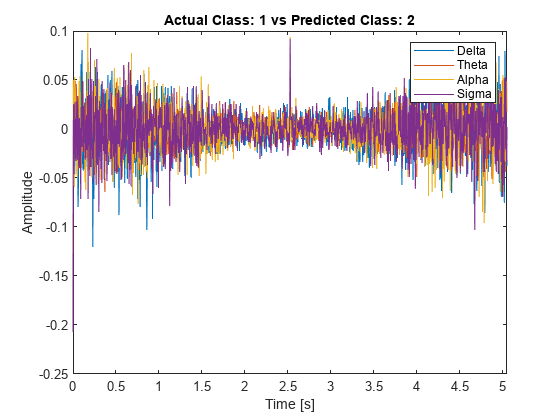

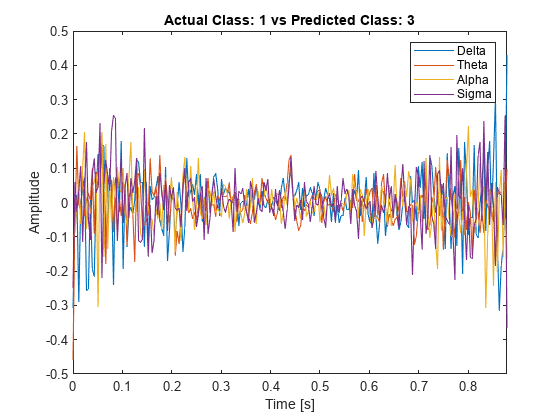

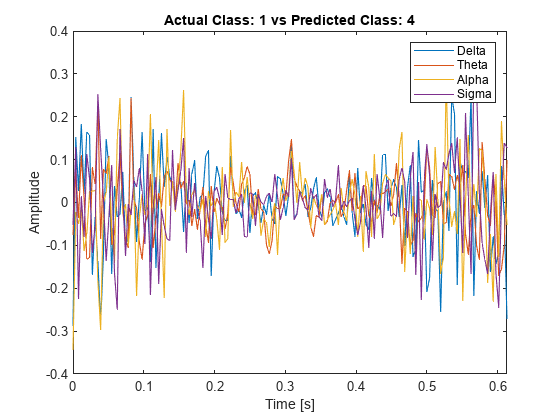

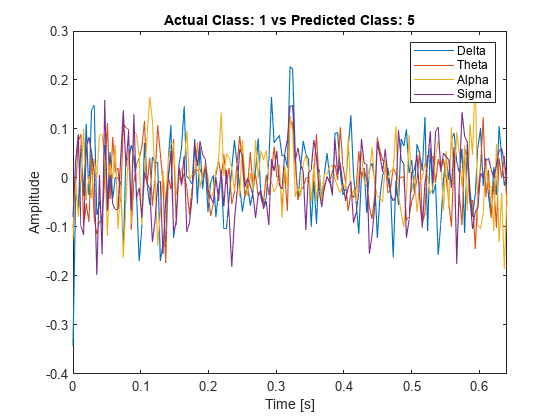

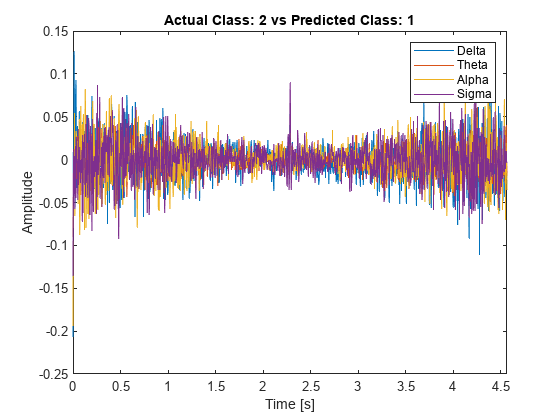

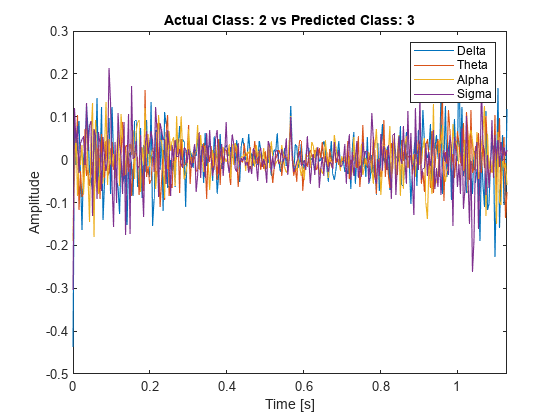

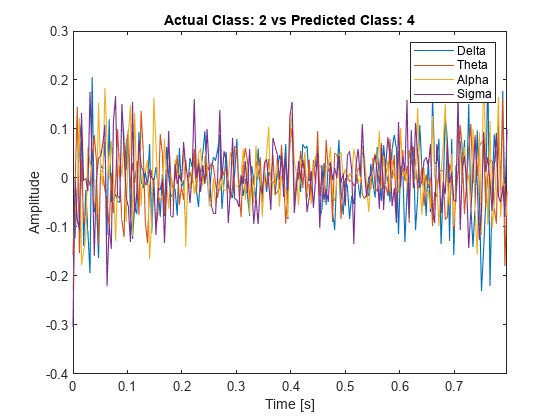

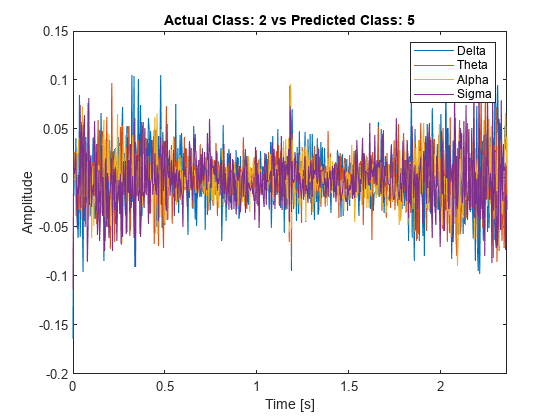

% Define the sampling frequency
fs = 256;

% Estimate the scaling factor based on the normalized data
mean_psd = mean(weightedXTrainMatrix(:));
std_psd = std(weightedXTrainMatrix(:));
scalingFactor = 1 / std_psd;  % Adjust this factor to increase the amplitude as needed

% Initialize an empty cell array to store time series data for each misclassification
timeSeriesDataPerMisclassification = cell(size(misclassifiedStages, 1), 1);

% Extract misclassified samples and generate time series data for each misclassification
for misclassificationIdx = 1:size(misclassifiedStages, 1)
    actualClass = categorical(misclassifiedStages{misclassificationIdx, 1}); % Actual class
    predictedClass = categorical(misclassifiedStages{misclassificationIdx, 2}); % Predicted class
    
    % Extract the rows corresponding to the misclassified samples in the testing data
    sampleIndex = find((YTrainLabels == actualClass) & (validationPredictions == predictedClass)); % Get sample indices
    spectralValues = weightedXTrainMatrix(sampleIndex, :); % Extract PSD values
    
    % Compute time series data from PSD values
    timeSeriesData = generate_time_series_from_psd(spectralValues, fs, scalingFactor);
    
    % Store time series data for the misclassification
    timeSeriesDataPerMisclassification{misclassificationIdx} = timeSeriesData;
end

% Define the frequency bands
frequencyBands = {'Delta', 'Theta', 'Alpha', 'Sigma'};

% Plot waveforms for each misclassification
for misclassificationIdx = 1:size(misclassifiedStages, 1)
    timeSeriesData = timeSeriesDataPerMisclassification{misclassificationIdx}; % Get time series data
    
    % Generate a time vector matching the length of timeSeriesData
    time = linspace(0, (size(timeSeriesData, 1) - 1) / fs, size(timeSeriesData, 1));

    % Find the maximum time value
    maxTime = max(time);
    
    % Extract actual and predicted class labels
    actualClass = misclassifiedStages{misclassificationIdx, 1};
    predictedClass = misclassifiedStages{misclassificationIdx, 2};
    
    % Plot the waveform
    figure;
    plot(time, timeSeriesData);
    title(['Actual Class: ' num2str(actualClass) ' vs Predicted Class: ' num2str(predictedClass)]);
    xlabel('Time [s]');
    ylabel('Amplitude');
    
    % Add a legend for each frequency band
    legend(frequencyBands, 'Location', 'northeast');

    % Set x-axis limit to the maximum time value
    xlim([0 maxTime]);
    
    % Save the plot as a PNG file
    filename = sprintf('Misclassification_Actual_%d_vs_Predicted_%d.png', actualClass, predictedClass);
    saveas(gcf, filename);
    
    % Optionally close the figure after saving to avoid too many open figure windows
    close(gcf);
end

function timeSeriesData = generate_time_series_from_psd(psdValues, fs, scalingFactor)
    % Apply the scaling factor to the PSD values
    scaled_psdValues = psdValues * scalingFactor;
    
    % Compute the amplitude spectrum from the scaled PSD
    amplitude_spectrum = sqrt(scaled_psdValues);
    
    % Generate random phases (or specify phase angles as desired)
    phase_angles = rand(size(amplitude_spectrum)) * 2 * pi; % Ensure phase_angles size matches amplitude_spectrum
    
    % Ensure phase angles at Nyquist frequency are either 0 or pi/2
    phase_angles(end) = 0; % For a real sequence
    
    % Handle complex components above Nyquist frequency
    if mod(size(amplitude_spectrum, 1), 2) == 0
        % Even number of samples, Nyquist frequency is sampled
        amplitude_spectrum_complex = [amplitude_spectrum; conj(flipud(amplitude_spectrum(2:end-1, :)))];
    else
        % Odd number of samples, Nyquist frequency is not sampled
        amplitude_spectrum_complex = [amplitude_spectrum; conj(flipud(amplitude_spectrum(2:end, :)))];
    end

    % Interpolate phase_angles to match the size of amplitude_spectrum_complex
    interpolated_phase_angles = interp1(linspace(0, fs/2, size(phase_angles, 1)), phase_angles, linspace(0, fs/2, size(amplitude_spectrum_complex, 1)), 'linear');

    % Perform element-wise multiplication with interpolated phase angles
    amplitude_spectrum_complex = amplitude_spectrum_complex .* exp(1i * interpolated_phase_angles);
    
    % Perform IFFT to obtain time series data
    timeSeriesData = ifft(amplitude_spectrum_complex, [], 1, 'symmetric');
end